clear;
rmdir('.\DataSet\', 's');
mkdir('.\DataSet\');

% 配置
config;
%-----------------------------
% 产生信号
source;
tag;
global y_sig;
y_sig = y_source .* y_tag;

global Length;
global Width;

## 房间内的随机点

N_inside = 50;
x = Width * rand(1, N_inside);
y = Length * rand(1, N_inside);

% 计算三个距离
[d1, d2, d3] = xy2d(x, y);

single_run(d1, d2, d3, false, 'inside');

delta t is
   1.0e-07 *

  列 1 至 16

    0.0718    0.1195    0.1794    0.1519    0.0682    0.1299    0.0511    0.1854    0.1913    0.1572    0.0460    0.0607    0.0462    0.1416    0.1622    0.1854

  列 17 至 32

    0.1017    0.1212    0.0359    0.1831    0.0623    0.0250    0.2031    0.1289    0.1867    0.0467    0.1086    0.1237    0.0311    0.0496    0.0591    0.1174

  列 33 至 48

    0.0296    0.1688    0.1463    0.0464    0.0970    0.1347    0.1783    0.0922    0.0986    0.0376    0.0597    0.1316    0.1836    0.1471    0.0185    0.1165

  列 49 至 50

    0.0763    0.0556



## 房间外的随机点

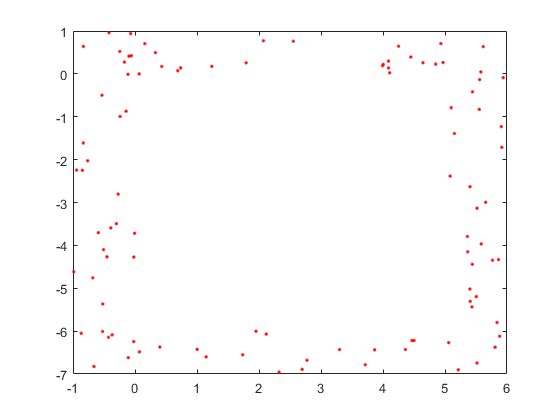

% 1/4 的数量
N_outside = 25;
x0 = rand(4, N_outside);
y0 = rand(4, N_outside);

x0 = [((Width / 2 + 1) * x0(:, 1:floor(N_outside / 2)))   (Width / 2 + x0(:, round(N_outside / 2) : end))];
y0 = [(Length / 2 + y0(:, 1:floor(N_outside / 2)))  ((Length / 2 + 1) * y0(:, round(N_outside / 2): end))];

x0(1,:) = -1 * x0(1, :);
x0(3,:) = -1 * x0(3, :);
y0(3,:) = -1 * y0(3, :);
y0(4,:) = -1 * y0(4, :);

% 坐标原点
x0 = x0 - (-1) * (Width / 2) * ones(size(x0));
y0 = y0 - 1 * (Length / 2) * ones(size(y0));

% 画出散点
% TODO: bugfix --- 点都集中在四个角落了，需要分散到边边上
figure; plot(x0,y0,'r.');


% 计算三个距离
[d1_0, d2_0, d3_0] = xy2d(x0, y0);
SinglePoint2(x0, y0, d1_0, d2_0, d3_0, false, 'outside');

delta t is
   1.0e-07 *

  列 1 至 16

    0.0451    0.0735    0.0298    0.0462    0.0414    0.0572    0.0208    0.0284    0.0389    0.0229    0.0246    0.0719    0.0297    0.0350    0.0301    0.0795
    0.2061    0.1762    0.2119    0.1925    0.1740    0.1803    0.1739    0.2233    0.1842    0.0921    0.1766    0.2177    0.2821    0.2512    0.3158    0.2652
    0.4094    0.4351    0.4192    0.4188    0.4133    0.4477    0.4350    0.4255    0.4855    0.4048    0.4510    0.4283    0.2898    0.3627    0.4439    0.2537
    0.5002    0.5338    0.5038    0.4912    0.5129    0.5539    0.5450    0.4866    0.4720    0.4761    0.4921    0.4879    0.4804    0.4414    0.3702    0.4380

  列 17 至 25

    0.1660    0.1956    0.1514    0.0337    0.1671    0.0651    0.0865    0.0418    0.1280
    0.3326    0.2593    0.3176    0.2850    0.3705    0.2843    0.2618    0.2664    0.3431
    0.3171    0.2799    0.4593    0.2549    0.2905    0.3237    0.4095    0.2397    0.2465
    0.4704    0.4119    0.5550  



% 保存样本点
filename = '.\DataSet\sample.mat'

filename = '.\DataSet\sample.mat'

save(filename, 'N_inside', 'N_outside', 'x', 'y', 'd1', 'd2', 'd3', 'x0', 'y0', 'd1_0', 'd2_0', 'd3_0');

## 数据预处理

% [] = preproc(filename, i, draw, isBeacon)
for i=1: N_inside
    preproc('i_sig_rx', i, false, 'inside');
end

% outside
for i=1: 4 * N_outside
    preproc('o_sig_rx', i, false, 'outside');
end